clear
prop = load_prop('prototype');
I__d_1 = prop.I__d_1;
I__d_2 = prop.I__d_2;
I__d_m_1 = prop.I__d_m_1;
I__d_m_2 = prop.I__d_m_2;
I__i_1 = prop.I__i_1;
I__i_2 = prop.I__i_2;
L_1 = prop.L_1;
L__d_g_1 = prop.L__d_g_1;
L__d_g_2 = prop.L__d_g_2;
L__i_g_1 = prop.L__i_g_1;
L__i_g_2 = prop.L__i_g_2;
g = prop.g;
m__d_1 = prop.m__d_1;
m__d_2 = prop.m__d_2;
m__i_1 = prop.m__i_1;
m__i_2 = prop.m__i_2;
n_1 = prop.n_1;
n_2 = prop.n_2;

syms t
syms psi_1_i psi_dot_1_i psi_1_f psi_dot_1_f T
syms psi_2_i psi_dot_2_i psi_2_f psi_dot_2_f

alpha_1 = psi_dot_1_f+2*psi_dot_1_i+2/T*(psi_1_i-psi_1_f);
psi_1(t) = (1-(t/T)^2)*(psi_1_i+psi_dot_1_i*t)+(t/T)^2*(psi_1_f+alpha_1*(t-T));
psi_1(t) = simplify(expand(psi_1(t)));
psi_1(t) = collect(psi_1,[t^3 t^2 t])

$$psi\_1(t) = \frac{2\,\psi_{1,i}-2\,\psi_{1,f}+T\,{\dot{\psi }}_{1,f}+T\,{\dot{\psi }}_{1,i}}{T^{3}}\,t^{3}+\left(-\frac{3\,T\,\psi_{1,i}-3\,T\,\psi_{1,f}+T^{2}\,{\dot{\psi }}_{1,f}+2\,T^{2}\,{\dot{\psi }}_{1,i}}{T^{3}}\right)\,t^{2}+{\dot{\psi }}_{1,i}\,t+\psi_{1,i}$$

psi_dot_1(t) = simplify(diff(psi_1,t));
psi_dot_1(t) = collect(psi_dot_1,[t^2 t])

$$psi\_dot\_1(t) = \frac{\left(2\,\psi_{1,i}-2\,\psi_{1,f}+T\,{\dot{\psi }}_{1,f}+T\,{\dot{\psi }}_{1,i}\right)\,3}{T^{3}}\,t^{2}+\left(-\frac{\left(3\,\psi_{1,i}-3\,\psi_{1,f}+T\,{\dot{\psi }}_{1,f}+2\,T\,{\dot{\psi }}_{1,i}\right)\,2}{T^{2}}\right)\,t+{\dot{\psi }}_{1,i}$$

psi_ddot_1(t) = simplify(diff(psi_dot_1,t));
psi_ddot_1(t) = collect(psi_ddot_1,[t])

$$psi\_ddot\_1(t) = \frac{\left(2\,\psi_{1,i}-2\,\psi_{1,f}+T\,{\dot{\psi }}_{1,f}+T\,{\dot{\psi }}_{1,i}\right)\,6}{T^{3}}\,t-\frac{\left(3\,\psi_{1,i}-3\,\psi_{1,f}+T\,{\dot{\psi }}_{1,f}+2\,T\,{\dot{\psi }}_{1,i}\right)\,2}{T^{2}}$$


alpha_2 = psi_dot_2_f+2*psi_dot_2_i+2/T*(psi_2_i-psi_2_f);
psi_2(t) = (1-(t/T)^2)*(psi_2_i+psi_dot_2_i*t)+(t/T)^2*(psi_2_f+alpha_2*(t-T));
psi_2(t) = simplify(expand(psi_2(t)));
psi_2(t) = collect(psi_2,[t^3 t^2 t])

$$psi\_2(t) = \frac{2\,\psi_{2,i}-2\,\psi_{2,f}+T\,{\dot{\psi }}_{2,f}+T\,{\dot{\psi }}_{2,i}}{T^{3}}\,t^{3}+\left(-\frac{3\,T\,\psi_{2,i}-3\,T\,\psi_{2,f}+T^{2}\,{\dot{\psi }}_{2,f}+2\,T^{2}\,{\dot{\psi }}_{2,i}}{T^{3}}\right)\,t^{2}+{\dot{\psi }}_{2,i}\,t+\psi_{2,i}$$

psi_dot_2(t) = simplify(diff(psi_2,t));
psi_dot_2(t) = collect(psi_dot_2,[t^2 t])

$$psi\_dot\_2(t) = \frac{\left(2\,\psi_{2,i}-2\,\psi_{2,f}+T\,{\dot{\psi }}_{2,f}+T\,{\dot{\psi }}_{2,i}\right)\,3}{T^{3}}\,t^{2}+\left(-\frac{\left(3\,\psi_{2,i}-3\,\psi_{2,f}+T\,{\dot{\psi }}_{2,f}+2\,T\,{\dot{\psi }}_{2,i}\right)\,2}{T^{2}}\right)\,t+{\dot{\psi }}_{2,i}$$

psi_ddot_2(t) = simplify(diff(psi_dot_2,t));
psi_ddot_2(t) = collect(psi_ddot_2,[t])

$$psi\_ddot\_2(t) = \frac{\left(2\,\psi_{2,i}-2\,\psi_{2,f}+T\,{\dot{\psi }}_{2,f}+T\,{\dot{\psi }}_{2,i}\right)\,6}{T^{3}}\,t-\frac{\left(3\,\psi_{2,i}-3\,\psi_{2,f}+T\,{\dot{\psi }}_{2,f}+2\,T\,{\dot{\psi }}_{2,i}\right)\,2}{T^{2}}$$


eom = [- I__i_2*(psi_ddot_1 - psi_ddot_2) + psi_ddot_1*(m__i_2*L_1^2 + 2*m__i_2*cos(psi_1 - psi_2)*L_1*L__i_g_2 + m__i_1*L__i_g_1^2 + m__i_2*L__i_g_2^2 + I__i_1 + I__i_2) + (m__d_2*L_1^2 + m__d_1*L__d_g_1^2 + I__d_m_1*n_1^2 + I__d_1)*psi_ddot_1 - L__i_g_2^2*m__i_2*(psi_ddot_1 - psi_ddot_2) + L_1*L__d_g_2*m__d_2*sin(psi_1 - psi_2)*psi_dot_2^2 + L_1*g*m__d_2*cos(psi_1) + L__d_g_1*g*m__d_1*cos(psi_1) + L_1*L__d_g_2*m__d_2*psi_ddot_2*cos(psi_1 - psi_2) + L_1*g*m__i_2*cos(psi_1) + L__i_g_1*g*m__i_1*cos(psi_1) + L__i_g_2*g*m__i_2*cos(psi_2) - L_1*L__i_g_2*m__i_2*cos(psi_1 - psi_2)*(psi_ddot_1 - psi_ddot_2) + L_1*L__i_g_2*m__i_2*sin(psi_1 - psi_2)*(psi_dot_1 - psi_dot_2)^2 - 2*L_1*L__i_g_2*m__i_2*psi_dot_1*sin(psi_1 - psi_2)*(psi_dot_1 - psi_dot_2); I__i_2*psi_ddot_1 - (m__i_2*L__i_g_2^2 + I__i_2)*(psi_ddot_1 - psi_ddot_2) + (m__d_2*L__d_g_2^2 + I__d_m_2*n_2^2 + I__d_2)*psi_ddot_2 - L_1*L__d_g_2*m__d_2*sin(psi_1 - psi_2)*psi_dot_1^2 + L__d_g_2*g*m__d_2*cos(psi_2) + L_1*L__d_g_2*m__d_2*psi_ddot_1*cos(psi_1 - psi_2) + L__i_g_2^2*m__i_2*psi_ddot_1 + L__i_g_2*g*m__i_2*cos(psi_2) - L_1*L__i_g_2*m__i_2*psi_dot_1^2*sin(psi_1 - psi_2) + L_1*L__i_g_2*m__i_2*psi_ddot_1*cos(psi_1 - psi_2)];
% diff_eom = diff(eom,t);


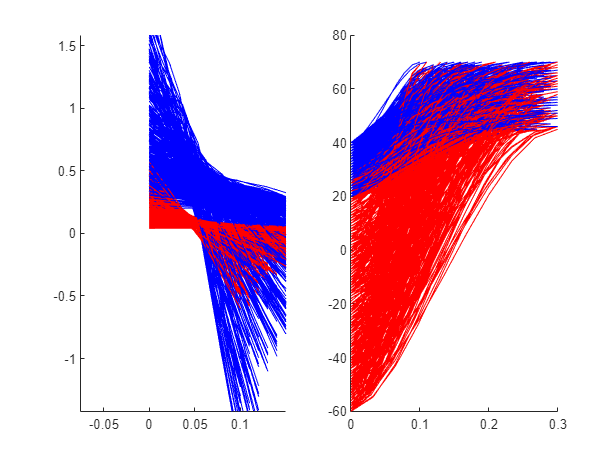

peak_ang = [45 70];
t_len = 10;
N = 100;
figure(1)
clf
tau_max_1 = [];
tau_max_2 = [];
idx_1 = [];
idx_2 = [];
for i = 1:N
    psi_1_i_new = randi([20 40])*pi/180;
    psi_dot_1_i_new = randi([50 200])*pi/180;
    psi_1_f_new = randi(peak_ang)*pi/180;
    psi_dot_1_f_new = 0;

    psi_2_i_new = randi([-60 30])*pi/180;
    psi_dot_2_i_new = randi([30 150])*pi/180;
    psi_2_f_new = randi(peak_ang)*pi/180;
    psi_dot_2_f_new = 0;
    T_new = randi([10 30])*1e-2;
    t_new = linspace(0,T_new,t_len);

    old_vars = [T psi_1_i psi_dot_1_i psi_1_f psi_dot_1_f...
        psi_2_i psi_dot_2_i psi_2_f psi_dot_2_f];
    new_vars = [T_new psi_1_i_new psi_dot_1_i_new psi_1_f_new psi_dot_1_f_new...
        psi_2_i_new psi_dot_2_i_new psi_2_f_new psi_dot_2_f_new];

    sub_eom = subs(eom,old_vars,new_vars);
    vec_eom = double(subs(sub_eom,t,t_new));
    tau_1 = vec_eom(1,:);
    tau_2 = vec_eom(2,:);
    [tau_max_1(i), idx_1(i)] = max(abs(tau_1));
    [tau_max_2(i), idx_2(i)] = max(abs(tau_2));

    psi_1_sub = subs(psi_1,[T psi_1_i psi_dot_1_i psi_1_f psi_dot_1_f],...
        [T_new psi_1_i_new psi_dot_1_i_new psi_1_f_new psi_dot_1_f_new]);
    psi_2_sub = subs(psi_2,[T psi_2_i psi_dot_2_i psi_2_f psi_dot_2_f],...
        [T_new psi_2_i_new psi_dot_2_i_new psi_2_f_new psi_dot_2_f_new]);
    psi_1_vec = double(subs(psi_1_sub,t,t_new));
    psi_2_vec = double(subs(psi_2_sub,t,t_new));

    figure(1)
    subplot(1,2,1)
    hold on
    plot(t_new,tau_1,'-b')
    plot(t_new,tau_2,'-r')
    subplot(1,2,2)
    hold on
    plot(t_new,psi_1_vec*180/pi,'-b')
    plot(t_new,psi_2_vec*180/pi,'-r')
end

nonends_1 = (idx_1 ~= 1).*(idx_1 ~= t_len);
avg_1 = 100*sum(nonends_1)/N

avg_1 = 3.8000


nonends_2 = (idx_2 ~= 1).*(idx_2 ~= t_len);
avg_2 = 100*sum(nonends_2)/N

avg_2 = 0.4000


torq_lim_1 = (tau_max_1 <= 1);
torq_lim_avg_1 = 100*sum(torq_lim_1)/N

torq_lim_avg_1 = 83.8000


torq_lim_2 = (tau_max_2 <= 0.4);
torq_lim_avg_2 = 100*sum(torq_lim_2)/N

torq_lim_avg_2 = 94.2000